Example-8: A Ferris wheel with a radius of 25 feet is rotating at a rate of 3 revolutions

per minute. When t = 0, a chair starts at the lowest point on the wheel, which is 5 feet

above the ground. Write a model for the height h (in feet) of the chair as a function of the time t (in seconds.

soln: The given example can be modelled using trigonometric function y = acoshx + A OR h=acos(bt) +k

Here h- height of the chair at any time t, t- time in seconds, a- amplitude, b=period, k- vertical shift

syms a b t k

f(t)=a*cos(b*t)+k

when the chair is at the bottom of the Ferris wheel, it is 5 feet % above the ground, so m=5

swhen it is at the top, it is 5 + 2(25) = 55 feet above the ground,

syms a b t k
f(t)=a*cos(b*t)+k

$$f(t) = k+a\,\cos\left(b\,t\right)$$

%when the chair is at the bottom of the Ferris wheel, it is 5 feet
% above the ground, so
m=5

m = 5

%when it is at the top, it is 5 + 2(25) = 55 feet above the ground,
M=5+2*25 % since r=25

M = 55

k=(M+m)/2 %vertical shift of the graph

k = 30


amp=(M-m)/2 %amplitude of the graph

amp = 25


%because minimum value occurs on the y axis is -ve
a=-amp

a = -25


%since the ferris wheelis rotating at 3 revolution per minute,
% it completes one revolution in 20 seconds.The period is 20
eq=(2*pi)/b==20

$$eq = \frac{2\,\pi }{b}=20$$


b=solve(eq,b)

$$b = \frac{\pi }{10}$$


f(t)=subs(f(t))

$$f(t) = 30-25\,\cos\left(\frac{\pi \,t}{10}\right)$$

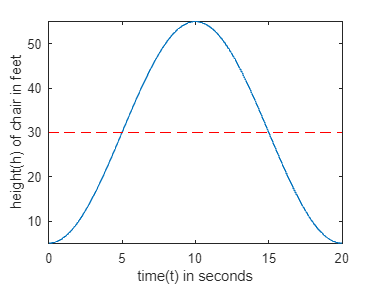


fplot(f(t),[0 20])
hold on 
plot([0 20],[30 30],'r--')
xlabel('time(t) in seconds')
ylabel('height(h) of chair in feet')
hold off